***逻辑基础***

**(1)逻辑运算符**

and函数 &运算符         均为1时返回1  只要有一个0就返回0

or函数  |运算符         只要有一个为1就返回1  所有都是0返回0

not函数 ~运算符         原来为1时返回0  原来为0时返回1

xor函数(亦或)                不相同时取1  相同时取0

A=randi([-3,3],2,4)

A =      0    -1    -3     1
     2     0    -2    -1


B=randi([-3,3],1,4)

B =      3    -3     3     0


%判断是否为0
A&B

ans = 2×4 logical 数组
   0   1   1   0
   1   0   1   0


A|B

ans = 2×4 logical 数组
   1   1   1   1
   1   1   1   1


~A

ans = 2×4 logical 数组
   1   0   0   0
   0   1   0   0


xor(3,4)

ans = logical
   0


xor(A,B)

ans = 2×4 logical 数组
   1   0   0   1
   0   1   0   1


逻辑运算可以连续运算

C=randi([-3,3],1,4)

C =      1     3    -1    -1


A&B&C

ans = 2×4 logical 数组
   0   1   1   0
   1   0   1   0


运算优先级

3>4&2>-1

ans = logical
   0


%大于号优先级大于逻辑运算符&     0&1=0
%等价于(3>4)&(2>-1)

应用示例

A=randi([0,100],1,20)

A =     46    77    82    10    17    36     5    52    33    17    21    91    68    47    92    10    75    74    56    18


res=(60<=A)&(A<80)

res = 1×20 logical 数组
   0   1   0   0   0   0   0   0   0   0   0   0   1   0   0   0   1   1   0   0


res2=~res

res2 = 1×20 logical 数组
   1   0   1   1   1   1   1   1   1   1   1   1   0   1   1   1   0   0   1   1


res3=(A<60)|(A>=80)

res3 = 1×20 logical 数组
   1   0   1   1   1   1   1   1   1   1   1   1   0   1   1   1   0   0   1   1


&&和||

(1)只能针对标量(只有一个元素)进行逻辑运算,不能对有多个元素的向量或者矩阵运算,而&和|可以

(2)具有短路功能,可以提高运行效率

计算A&&B时,如果A为逻辑0,则B不会被判断,因为结果一定是逻辑0

计算A||B时,如果A为逻辑1,则B不会被判断,因为最后结果一定是逻辑1

**(2)函数**

all判断数组元素是否全为非零值,全为非零值时返回逻辑1,否则返回逻辑0

any判断数组元素中是否至少存在一个非零值,是的话返回1,不是就返回0

clear;
clc;
B=randi([0,100],2,5)

B =     17    77    10    10    19
    83    94    18    49    90


B(3)=0;
B;
all(B,1);
all(B,2);
any(B,1);
any(B,2);

应用实例

score=randi([50,100],5,3)

score =     55    59    82
    52    67    55
    78    60    69
    89    76    52
    65    96    75


any(score<60,2);

效果:

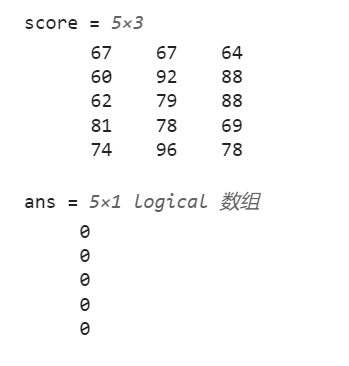

all(score>=60,1)

ans = 1×3 logical 数组
   0   0   0


find函数:查找数组中的非零元素,并返回其索引

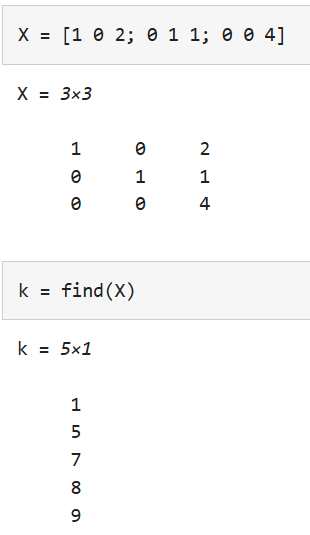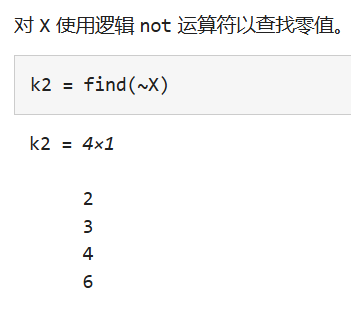

A=randi([0,2],2,3)

A =      1     2     2
     2     1     0


ind=find(A)

ind =      1
     2
     3
     4
     5


ind2=find(A,2)

ind2 =      1
     2


ind3=find(A,2,'last')

ind3 =      4
     5


[row,col]=find(A)

row =      1
     2
     1
     2
     1


col =      1
     1
     2
     2
     3


[row,col,v]=find(A)

row =      1
     2
     1
     2
     1


col =      1
     1
     2
     2
     3


v =      1
     2
     2
     1
     2


应用实例

score=randi([50,100],5,3)

score =     69    67    92
    97    97    70
    96    56    88
    86    87    92
    81    82    66


find(sum(score<60,2)==1)

ans = 3

%找出只有一项少于60的行号
find(sum(score,2)>260)

ans =      2
     4


%利用sum将其改为列向量,再利用find找出行号